# Visualize and Recreate EWT Decomposition

This example shows how to visualize an empirical wavelet transform (EWT) decomposition using Signal Multiresolution Analyzer. You learn how to compare two different decompositions in the app, and how to recreate a decomposition in your workspace.

Create a noisy signal, `sig`, composed of three main components:

- A 60 Hz component between 0.1 and 0.3 seconds

- A 200 Hz component between 0.7 and 1 second

- A trend term

Sample the signal at 1000 Hz for one second.

Fs = 1e3;
t = 0:1/Fs:1-1/Fs;
comp1 = cos(2*pi*200*t).*(t>0.7);
comp2 = cos(2*pi*60*t).*(t>=0.1 & t<0.3);
trend = sin(2*pi*1/2*t);
rng default
wgnNoise = 0.4*randn(size(t));
sig = comp1+comp2+trend+wgnNoise;

## Visualize EWT

Open Signal Multiresolution Analyzer and click **Import**. Select `sig` and click **Import**. By default, a four-level MODWTMRA decomposition appears in the **MODWT** tab. In the **Signal Multiresolution Analyzer** tab, set the sample rate to 1000 Hz.

To generate an MRA decomposition using the empirical wavelet transform (EWT), go to the **Signal Multiresolution Analyzer** tab. Click **Add** ▼ and select **EWT**.

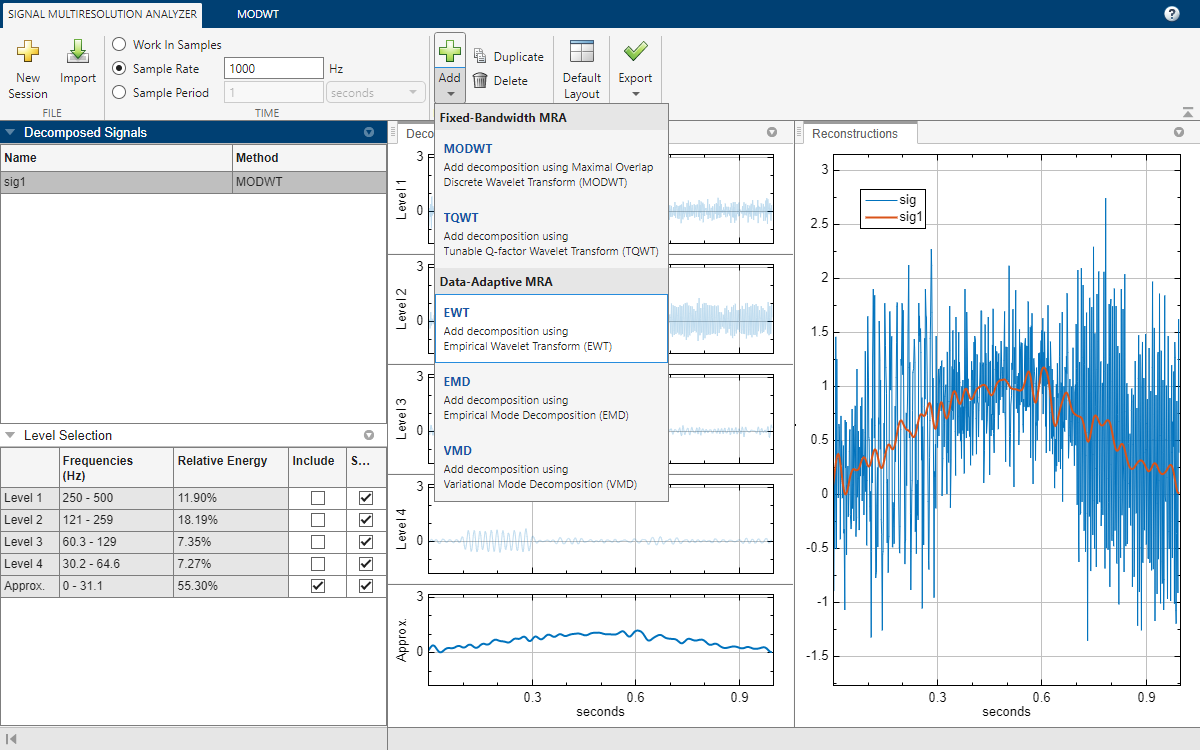

After a few moments, the EWT decomposition `sig2` appears in the **EWT** tab. The app obtains the decomposition using the [ewt](docid:wavelet_ref#mw_0f546a3f-6699-4774-8ad0-a2bb00ce8325) function with default settings. The **Level Selection** pane shows the relative energies of the signal across the passbands, as well as the measured frequency ranges. With the toolstrip, you can change the EWT parameters to generate a different decomposition. You can:

- Specify how to choose the peaks that determine the passbands.

- Specify the frequency resolution bandwidth of the multitaper power spectral estimate. The value determines the number of sine tapers the app uses in the multitaper power spectrum estimate.

- Choose whether or not to use the log of the multitaper power spectrum to determine the peak frequencies.

- Choose either the geometric mean of adjacent peaks or the first local minimum between adjacent peaks to determine the passbands.

Changing a value enables the **Decompose** button. To learn more about the parameters, see [ewt](docid:wavelet_ref#mw_0f546a3f-6699-4774-8ad0-a2bb00ce8325) and [Empirical Wavelet Transform](docid:wavelet_ug#mw_4b21bfac-a7da-4110-b6e8-960eb2c9d501).

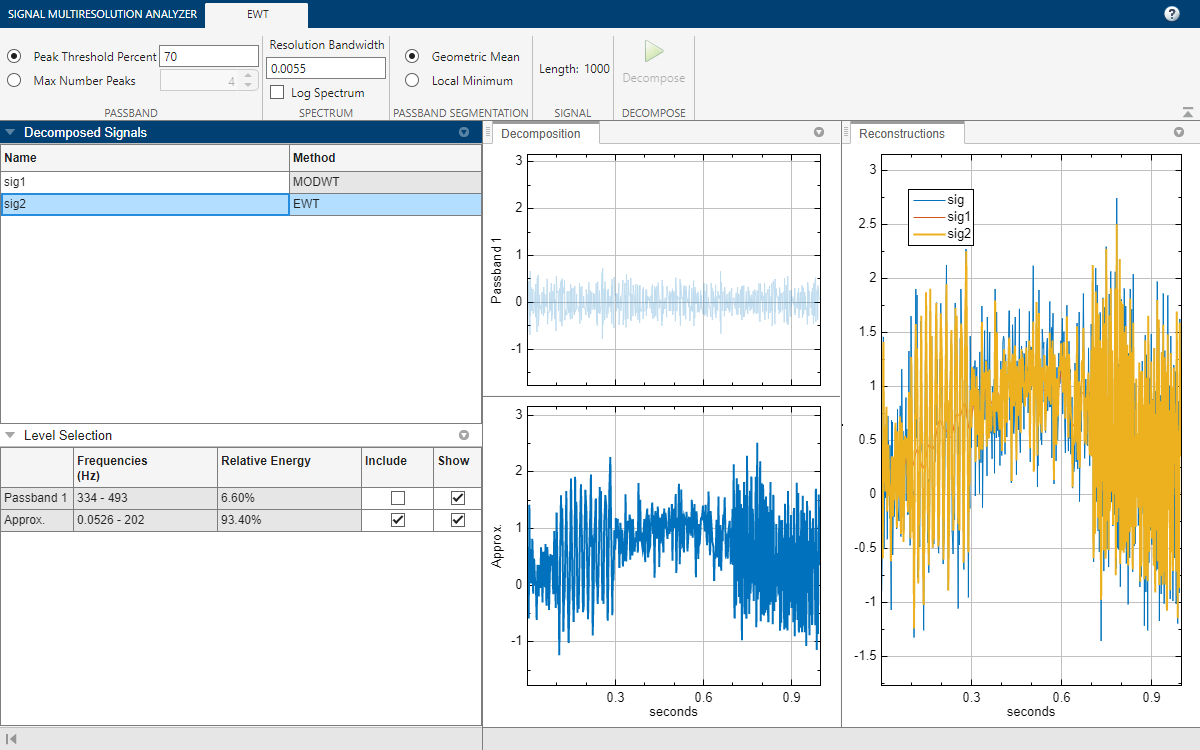

## Change Peak Identification Method

By default, the `ewt` function uses a threshold to determine which peaks to retain in the multitaper power spectrum of the signal. In the case of `sig`, `ewt` found two passbands. You can also choose the *N* largest peaks. To compare the two methods, select `sig2`, and on the **Signal Multiresolution Analyzer** tab, click **Duplicate**. A duplicate, `sig2Copy`, appears. In the **EWT** tab, set the value of **Max Number Peaks** to 5 and click **Decompose**. The result is a decomposition with five passbands.

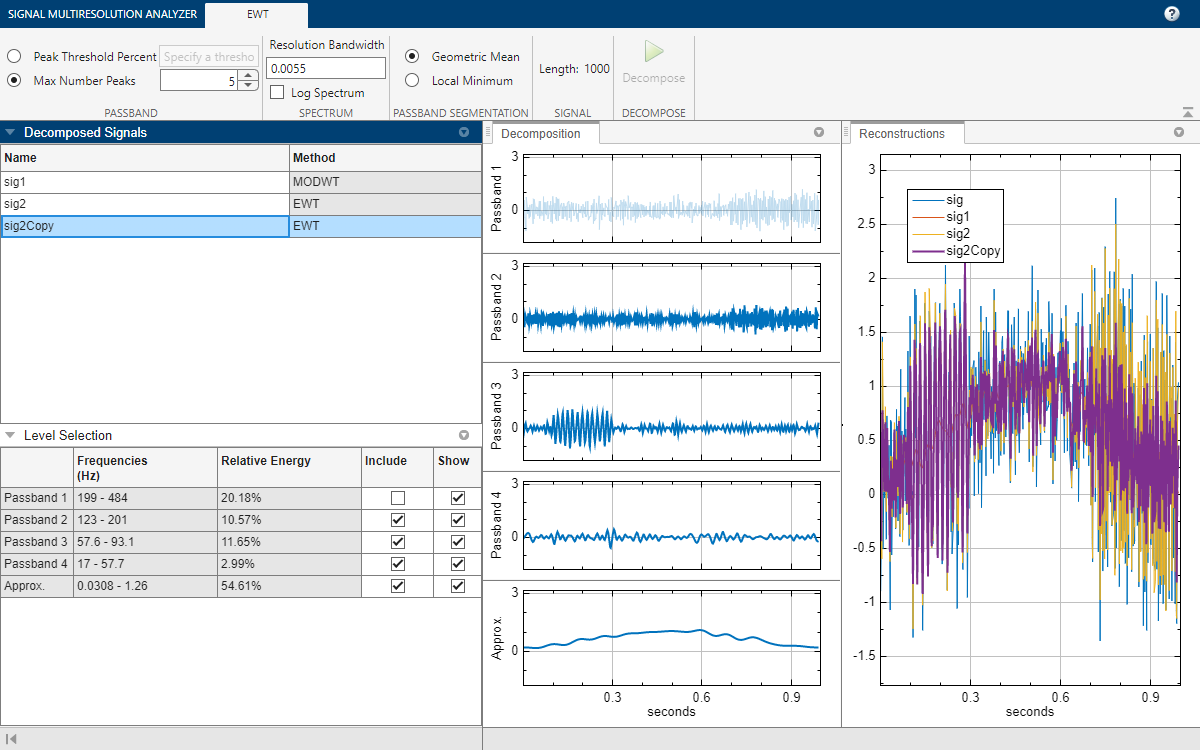

You can compare the `sig2Copy` approximation with the `sig1` approximation by first removing passbands 2 through 4 from the `sig2Copy` reconstruction, and then clicking `sig` and `sig2` in the legend in the **Reconstructions** pane. To remove a passband from the reconstruction, you can either clear the corresponding **Include** box in the **Level Selection** pane or click on the plot of the passband in the **Decomposition** pane.

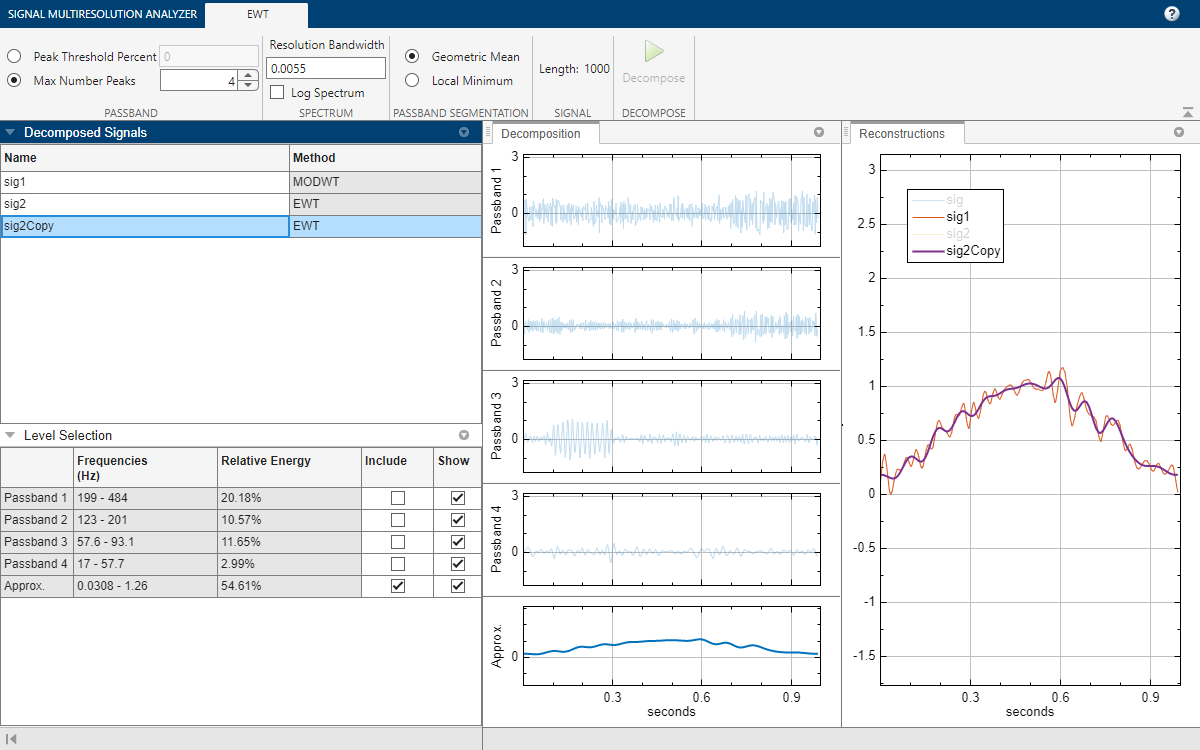

## Export Script

To recreate the decomposition in your workspace, in the **Signal Multiresolution Analyzer** tab click **Export** > **Generate MATLAB Script**. An untitled script opens in your editor with the following executable code. The true-false values in `levelForReconstruction` correspond to the `Include` boxes you selected in the **Level Selection** pane. You can save the script as is or modify it to apply the same decomposition settings to other signals. Run the code.

% Logical array for selecting reconstruction elements
levelForReconstruction = [false,false,false,false,true];

% Perform the decomposition using ewt
[mra,cfs,wfb,info] = ewt(sig, ...
    MaxNumPeaks=5, ...
    SegmentMethod='geomean', ...
    FrequencyResolution=0.0055, ...
    LogSpectrum=false);

% Sum down the rows of the selected multiresolution signals
sig2Copy = sum(mra(:,levelForReconstruction),2);

The columns in the MRA matrix `mra` correspond to the passbands and approximation in the **Level Selection** pane. Plot the passbands, and confirm they are identical with those in the app.

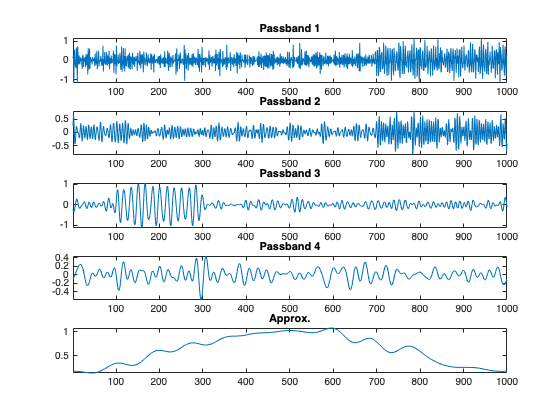

numplots = size(mra,2);
figure
for k=1:numplots
    subplot(numplots,1,k)
    plot(mra(:,k))
    if k~=numplots
        title(["Passband "+num2str(k)])
    else
        title("Approx.")
    end
    axis tight
end

*Copyright 2021 The MathWorks, Inc.*